# Hyper- reduction POD_DEIM Implementation for  Non-lInear System

## Recall POD for Linear Systems 

 that is, let's create the **snapshot matrix**


$$X = \left[ x^{t_1} ,  x^{t_2} ,  x^{t_3} , \cdots,  x^{t_s} \right]$$


For LTI, teh ODE is


$$ \dot x = Ax  + Bu; \quad y= Cx+Du$$


close all; clear; clc

Generate Random Linear-time invarant (LTI) System

n = 1000;
% rng(SD) seeds the random number generator using the non-negative
%    integer SD so that RAND, RANDI, and RANDN produce a predictable
%    sequence of numbers.
rng(2) 

% Generate the random LTI
sys = rss(n);
A = sys.a;
B = sys.b;
C = sys.c;
D = 0;

## POD for Non-Linear Systems - Introduce nonlienarities

### ***Let's keep the same system, but introduce a non-linearity -*** 


$$ \dot x = f(t, x, u) $$


**see notes on the particualr case we are working**


$$ \dot x = Ax + f(t, x, u) + Bu$$


In this case, we will use a simple exponential decay function


$$f = \alpha e^{-0.1x}$$


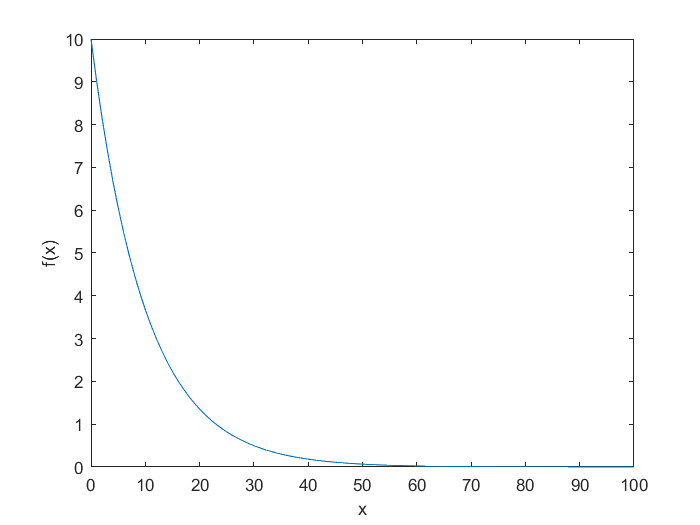

% Nonlinearity
alpha = 10;
f = @(x) alpha*exp(-0.1*x);

% Check the form of nonlinearity 
x = linspace(0, 100, 100);
Fx = f(x);
figure 
plot(x, Fx)
xlabel('x'); ylabel('f(x)');

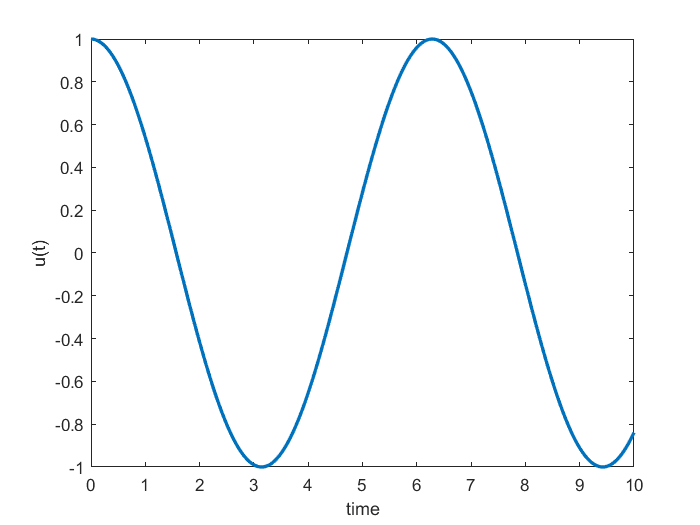



% Setup the simulation conditions -= that is when to get snapshots
t_start = 0;
t_final = 10;
time = linspace(t_start, t_final, 200);

% Input
inp = 1;
if inp == 1
    u = @(t) cos(t);
else 
    u = @(t) exp(-t).*cos(pi*t);
end

u_time = u(time);
figure;
plot(time, u_time, 'LineWidth', 2)
xlabel('time'); ylabel('u(t)');


% New Differnential Equation
dx2 = @(t,x, A, B) A*x + f(x) + B*u(t);
options = odeset('RelTol',1e-4, 'AbsTol',1e-6);

**Let's re-introduce the new IC, time span, etc**

% New IC
x0 = zeros(n,1);

% simulate and measure time to simulation
tic
[t_sol_NL, x_sol_NL] = ode45(dx2, time, x0, options, A, B);
time_NL_FOM = toc

time_NL_FOM = 0.5894

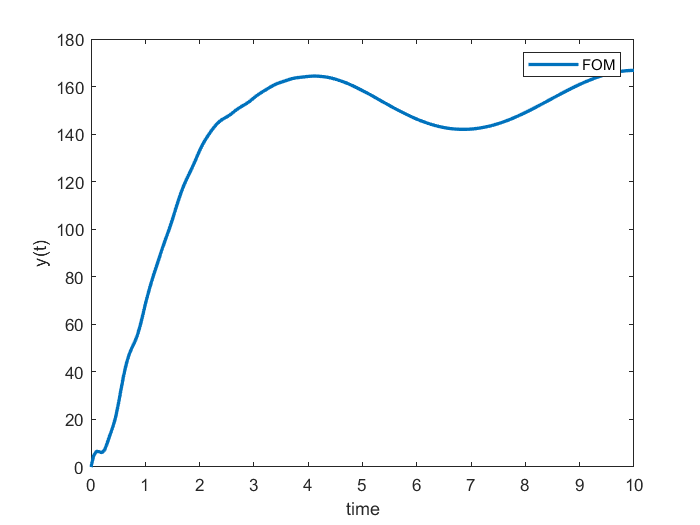


% Store snapshots
X_NL = x_sol_NL';

% Compute Output
y_NL = C*X_NL;

figure;
plot(t_sol_NL, y_NL, 'LineWidth',2);
xlabel('time'); ylabel('y(t)');
legend('FOM')

**Let's perform POD**

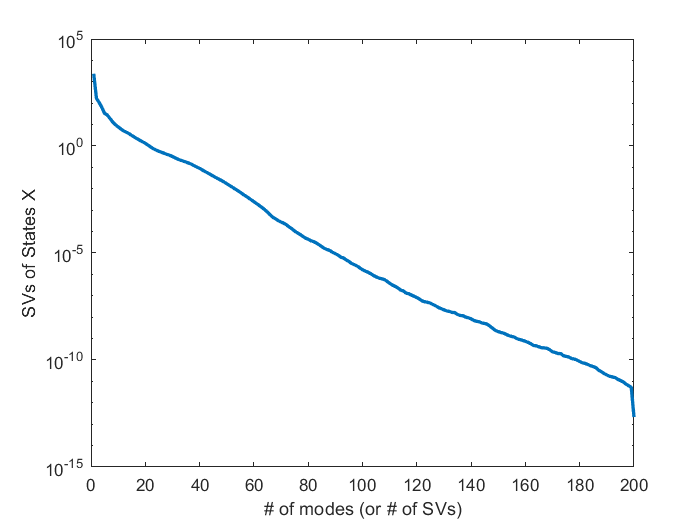

[U, Sigma, W]  =svd(X_NL, 'econ');
figure
semilogy(diag(Sigma), 'LineWidth',2)
xlabel('# of modes (or # of SVs)'); ylabel('SVs of States X');


% POD basis
r = 50;
V = U(:,1:r);

**Let's project**

% Project onto linear part

Ar = V'*A*V;
Br = V'*B;
Cr = C*V;
Dr = D;

% Intial Condition on reduced space
z0  = V'*x0;

% Project onto non-linear part
dxPOD = @(t,z, Ar, Br) Ar*z + V'*f(V*z) + Br*u(t);

% Simulate 
tic
[t_sol, z_sol] = ode45(dxPOD, time, z0, options, Ar, Br);
time_POD_NL = toc

time_POD_NL = 0.1141

**Note: Computation of Reduced order model stills depend on teh Full state X - Need to use Hyper Reduction (POD-DEIM) for Non-Linear Systems**

**Check solution -= project back to FOM **

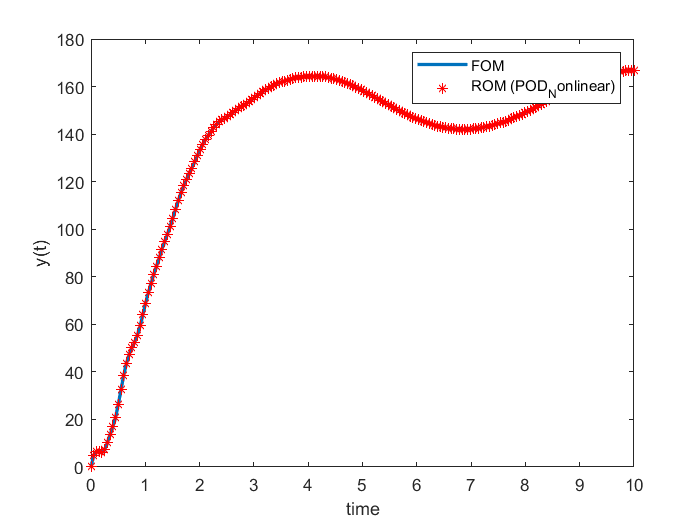

% FOM approximate states
X_POD_NL = V*(z_sol)';
% Apprzimate Output
yr_POD_NL = C*X_POD_NL;

% Plot
figure
plot(t_sol, y_NL, 'LineWidth',2);
hold on
plot(t_sol, yr_POD_NL, 'r*')
xlabel('time'); ylabel('y(t)');
legend('FOM', 'ROM (POD_Nonlinear)')

##  Hyper Reduction (POD-DEIM) for Non-Linear Systems

### DEIM Algorithm 

Get Snapshots of teh nonlinear functioin - f(x)

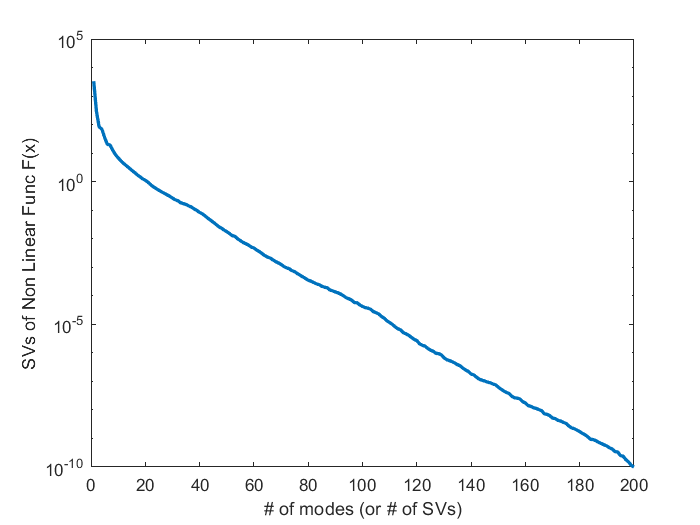

% Snapshots of nonlinear function
% This could have been done on-the-fly, but since we already have X, in
% this case, it is just a matter of evaluating F(X).

for i = 1: size(X_NL,2)
    F(:,i) = f(X_NL(:,i));
end

% Compute SVD
[Uf, Sigmaf, Wf] = svd(F, 'econ');

figure
semilogy(diag(Sigmaf), 'LineWidth',2)
xlabel('# of modes (or # of SVs)'); ylabel('SVs of Non Linear Func F(x)');

Select how many modes for the nonlienar function --> it does not ahve to be equal to r

l = 50;
Ud = Uf(:, 1:l);

DEIM ALGORITHM - SEE NOTES

%v DEIM Agorithm
U = Ud(:,1); % Start by getting teh first vector of Ud --> store in the basis U
[~, Index] = max(abs(U));
P = Index;

% Generate all the basis, by computing next indexes into a Greedy algorithm
for i = 2:l
    % Get coefficient c
    c = U(P,:)\Ud(P,i);
    % Compute residual
    res_vec = Ud(:, i) - U*c;
    % next index is the row with largest residual
    [~, Index] = max(abs(res_vec));
    P(i) = Index;
    % Augument the basis
    U = [U Ud(:, i)]; 
end

% Notice that P'*U = U(indices, :)
% So this can be precompute - offline

UPU = U/(U(P, :));
VUPU = V'*(UPU);

Vres = V(P,:);

Now, we are ready to simulate POD-DEIM

dxPOD_DEIM = @(t,z, Ar, Br) Ar*z + VUPU*f(Vres*z) + Br*u(t);


% Simulate 
tic
[t_sol, z_sol] = ode45(dxPOD_DEIM, time, z0, options, Ar, Br);
time_POD_DEIM = toc

time_POD_DEIM = 0.0295

Check final (POD-DEIM) solution

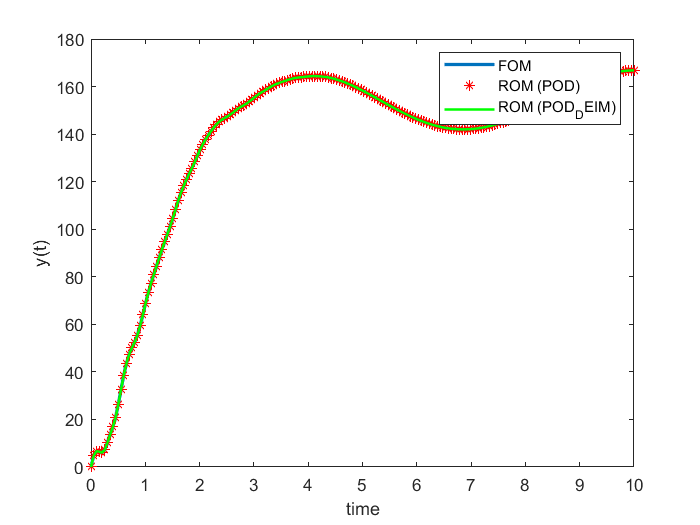

X_POD_DEIM = V*(z_sol)';

yr_POD_DEIM = C*X_POD_DEIM;

% Plot
figure
plot(t_sol, y_NL, 'LineWidth',2);
hold on
plot(t_sol, yr_POD_NL, 'r*')
plot(t_sol, yr_POD_DEIM, 'g','LineWidth', 1.5)
xlabel('time'); ylabel('y(t)');
legend('FOM', 'ROM (POD)', 'ROM (POD_DEIM)')